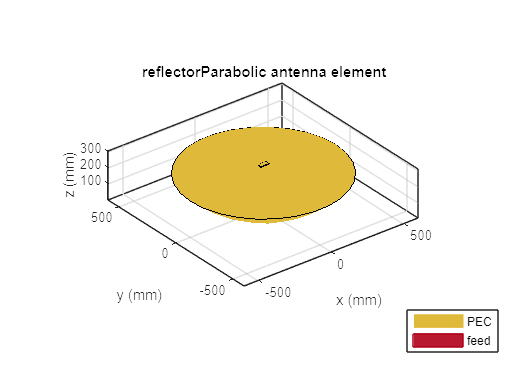

f = 5.4e9;
lambda = 299792458/f;

patch = patchMicrostrip('Length',0.4*lambda,'Width',0.4*lambda, 'Substrate', dielectric('Air'), 'FeedOffset', [0, 0], 'GroundPlaneLength', lambda/2, 'GroundPlaneWidth', lambda/2);
array = linearArray('Element', patch, 'Numelements', 2, 'ElementSpacing', 0.58*lambda, 'Tilt', 180);
ant = reflectorParabolic('Exciter',array, 'Radius', 0.5, 'FocalLength', 0.28);

show(ant);

[x] = patternAzimuth(ant, 5.4e9);
x_abs = 10.^(x./10)

x_abs =     0.2359
    0.2250
    0.2069
    0.1886
    0.1757
    0.1670
    0.1572
    0.1451
    0.1369
    0.1395



save("radiation_pattern.mat", 'x_abs')

%patternElevation(ant, 5.4e9)
%pattern(ant, 5.4e9)